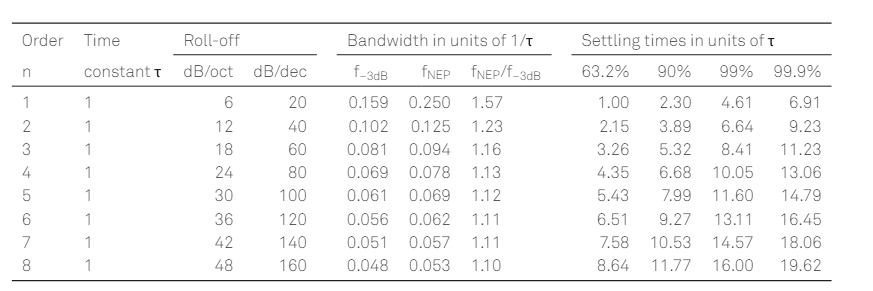

%IDEAL order 2 FILTER%

%%calculate wc from alpha, alpha = 1-(1-sin(wc))/cos(wc);
%wc = asec((-alpha^2 + 2*alpha-2)/(2*(alpha-1)));
%fc=wc/(2*pi)*fs
%tau=1/(2*pi*fc)

fc_wanted = 500000

fc_wanted = 500000

fs = 50000000

fs = 50000000


%for order 8
tau = 0.048 * 1 / fc_wanted;
fc_single = 1/(2*pi*tau);
wc = fc_single/fs * 2 * pi;
alpha = 1-(1-sin(wc))/cos(wc);
%alpha = 2^-26


disp(['Da mettere nella testBench per alpha: ', fi([alpha],1,27,26).bin])

Da mettere nella testBench per alpha: 000110000011101011111001101



tustin_num = alpha/2*[1 1];
tustin_den = [1 -(1-alpha)];
tustin_iir = dsp.IIRFilter('Numerator',tustin_num,'Denominator',tustin_den);
cascading = dsp.FilterCascade(tustin_iir, tustin_iir, tustin_iir, tustin_iir,tustin_iir, tustin_iir, tustin_iir, tustin_iir)

cascading =   dsp.FilterCascade with properties:

         Stage1: [1×1 dsp.IIRFilter]
         Stage2: [1×1 dsp.IIRFilter]
         Stage3: [1×1 dsp.IIRFilter]
         Stage4: [1×1 dsp.IIRFilter]
         Stage5: [1×1 dsp.IIRFilter]
         Stage6: [1×1 dsp.IIRFilter]
         Stage7: [1×1 dsp.IIRFilter]
         Stage8: [1×1 dsp.IIRFilter]
    CloneStages: true


fvtool(tustin_iir,'Fs',fs);
fvtool(cascading,'Fs',fs);